clear all;
close all;
clc;

gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.45.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab');
changeCobraSolver('gurobi', 'all');


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
Gurobi error 10009: License expired 2024-05-14
Please consult the Gurobi Quick Start Guide for details on setting up a license.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
Gurobi error 10009: License expired 2024-05-14
Please consult the Gurobi Quick Start Guide for details on setting up a license.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 

# PLOTS

This code makes sure to plot the core genes and core reactions inclussion, as well as to provide a better undersanding of the GPR rules

% load the data
metabolic_genes = load("metabolic_genes.mat");
metabolic_genes = metabolic_genes.metabolic_genes;
metabolic_genes_P = load("metabolic_genes_P.mat");
metabolic_genes_P = metabolic_genes_P.metabolic_genes_P;
gene_names_P = metabolic_genes_P.Properties.RowNames;

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
h_k_g = readtable('NM2ENSG.xlsx');
%[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
%model_p = fluxConsistModel; % load the new model with no blocked reactions
%save('model_p.mat', 'model_p');
model_p = load('model.mat');
model_p = model_p.model;
cd(currentFolder)

## Housekeeping

%hk_gene_new = table2cell(hk_gene_new);
hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));

% To reactions
results_HKReact = findRxnsFromGenes_Alicia(model_p, hkg_met);

Input: string of single gene or cell array of multiple genes



% Extract unique housekeeping reaction names
fields = fieldnames(results_HKReact);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = results_HKReact.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react_unique = unique(housekeep_react);
disp(housekeep_react_unique);

    {'MAR00001'}
    {'MAR00003'}
    {'MAR00005'}
    {'MAR00006'}
    {'MAR00010'}
    {'MAR00067'}
    {'MAR00080'}
    {'MAR00091'}
    {'MAR00113'}
    {'MAR00114'}
    {'MAR00115'}
    {'MAR00117'}
    {'MAR00118'}
    {'MAR00121'}
    {'MAR00122'}
    {'MAR00129'}
    {'MAR00133'}
    {'MAR00153'}
    {'MAR00154'}
    {'MAR00155'}
    {'MAR00158'}
    {'MAR00164'}
    {'MAR00167'}
    {'MAR00170'}
    {'MAR00173'}
    {'MAR00176'}
    {'MAR00179'}
    {'MAR00183'}
    {'MAR00187'}
    {'MAR00188'}
    {'MAR00190'}
    {'MAR00191'}
    {'MAR00192'}
    {'MAR00195'}
    {'MAR00196'}
    {'MAR00199'}
    {'MAR00200'}
    {'MAR00203'}
    {'MAR00204'}
    {'MAR00208'}
    {'MAR00209'}
    {'MAR00212'}
    {'MAR00213'}
    {'MAR00216'}
    {'MAR00217'}
    {'MAR00225'}
    {'MAR00226'}
    {'MAR00232'}
    {'MAR00233'}
    {'MAR00236'}
    {'MAR00237'}
    {'MAR00240'}
    {'MAR00241'}
    {'MAR00244'}
    {'MAR00245'}
    {'MAR00248'}
    {'MAR00249'}
    {'MAR00254'}
    {'MAR00255

HK_rxns = find_housekeeping_reactions(model_p, hkg_met, 'strict')

HK_rxns = 1×1836 cell array
    {'MAR03905'}    {'MAR03907'}    {'MAR04097'}    {'MAR04108'}    {'MAR04133'}    {'MAR04281'}    {'MAR04388'}    {'MAR08357'}    {'MAR04360'}    {'MAR04365'}    {'MAR04368'}    {'MAR04371'}    {'MAR04381'}    {'MAR04391'}    {'MAR03989'}    {'MAR08592'}    {'MAR08589'}    {'MAR03944'}    {'MAR04130'}    {'MAR04131'}    {'MAR04132'}    {'MAR04303'}    {'MAR04414'}    {'MAR08767'}    {'MAR04383'}    {'MAR04400'}    {'MAR04401'}    {'MAR04402'}    {'MAR04706'}    {'MAR08768'}    {'MAR08341'}    {'MAR08344'}    {'MAR08727'}    {'MAR08729'}    {'MAR06537'}    {'MAR03853'}    {'MAR03857'}    {'MAR04087'}    {'MAR04091'}    {'MAR08497'}    {'MAR08500'}    {'MAR08501'}    {'MAR08502'}    {'MAR08503'}    {'MAR08504'}    {'MAR08506'}    {'MAR08507'}    {'MAR08508'}    {'MAR08509'}    {'MAR08511'}    {'MAR08516'}    {'MAR00153'}    {'MAR03212'}    {'MAR03797'}    {'MAR04331'}    {'MAR04459'}    {'MAR04460'}    {'MAR09804'}    {'MAR03163'}    {'MAR04052'}    {'MAR043

## Start the ploting


% % Pruned and unpruned data
%IMR90_Y2 = table2array(metabolic_genes(:, 8));
IMR90_Y2 = table2array(mean(metabolic_genes(:, 8), 2))

IMR90_Y2 =     2.0923
    2.2535
    1.3807
    0.5487
    1.7719
    0.0457
    0.0734
    0.1856
    0.0866
    0.3394


%IMR90_Y2_P = table2array(metabolic_genes_P(:, 8));
IMR90_Y2_P = table2array(mean(metabolic_genes_P(:, 8), 2))

IMR90_Y2_P =     2.0923
    2.2535
    1.3807
    0.5487
    1.7719
    0.0457
    0.0734
    0.0866
    0.3394
    1.7364



% Core genes and core reactions
%IMR90_Y2_coreGenes = results_CoreGenes(8, 'CoreGeneIDs');
%test = IMR90_Y2_coreGenes{1, 1};
IMR90_Y2_length = length(IMR90_Y2_P);

% for core Reactions
%IMR90_Y2_coreReact = CoreReact_Sample(1, 8)
IMR90_Y2_RLength = length(model_p.rxns);%IMR90_Y2_coreReact{1, 1})

% Initialises vectors for storing recall values
HK_CG_G = zeros(1, 100);
HK_CR_R = zeros(1, 100);
HK_CG_G_recall_values = zeros(1, 100);
HK_CR_R_recall_values = zeros(1, 100);

% Loop to iterate over each percentile
for p = 1:100
    percentile_value = prctile(IMR90_Y2, p);

    % Normalises data based on the current percentile
    IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;

    % Calculate the recall for core genes
    IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
    HK_CG_G(p) = (length(IMR90_Y2_CG)/IMR90_Y2_length)*100;
    HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
    HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
    HK_CG_G_recall_values(p) = HK_CG_G_recall;

    % Prepare the expression data
    expressionData.gene = gene_names_P;
    expressionData.value = IMR90_Y2_norm;

    % Map gene expression to reactions
    IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false'); % Maybe here with the pruned one?
    IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);

    % Calculate the recall for core reactions
    HK_CR_R(p) = (length(IMR90_Y2_CR)/IMR90_Y2_RLength)*100;
    HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
    HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
    HK_CR_R_recall_values(p) = HK_CR_R_recall;
end

## Save the results and load them

save('HK_CG_G_1.mat', 'HK_CG_G');
save('HK_CG_G_recall_values_1.mat', 'HK_CG_G_recall_values');
save('IMR90_Y2_norm_1.mat', 'IMR90_Y2_norm');
save('IMR90_Y2_normCR_1.mat', 'IMR90_Y2_normCR');
save('HK_CR_R_1.mat', 'HK_CR_R');
save('HK_CR_R_recall_values_1.mat', 'HK_CR_R_recall_values');
% Load the data
HK_CG_G = load('HK_CG_G_1.mat');
HK_CG_G = HK_CG_G.HK_CG_G;
HK_CG_G_recall_values = load('HK_CG_G_recall_values_1.mat');
HK_CG_G_recall_values = HK_CG_G_recall_values.HK_CG_G_recall_values;
IMR90_Y2_norm = load('IMR90_Y2_norm_1.mat');
IMR90_Y2_norm = IMR90_Y2_norm.IMR90_Y2_norm;
IMR90_Y2_normCR = load('IMR90_Y2_normCR_1.mat');
IMR90_Y2_normCR = IMR90_Y2_normCR.IMR90_Y2_normCR;
HK_CR_R = load('HK_CR_R_1.mat');
HK_CR_R = HK_CR_R.HK_CR_R;
HK_CR_R_recall_values = load('HK_CR_R_recall_values_1.mat');
HK_CR_R_recall_values = HK_CR_R_recall_values.HK_CR_R_recall_values;

## Plot the results

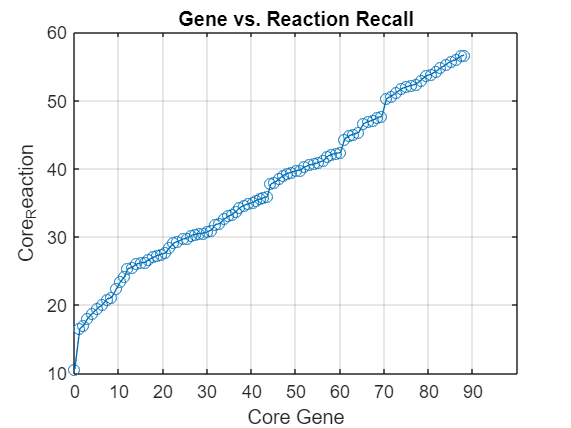

% CORE GENE INCLUSSION VS CORE REACTION INCLUSION
plot(HK_CG_G, HK_CR_R, 'o-');
xlabel('Core Gene');
ylabel('Core_Reaction');
title('Gene vs. Reaction Recall');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_Reaction_Mean.png');

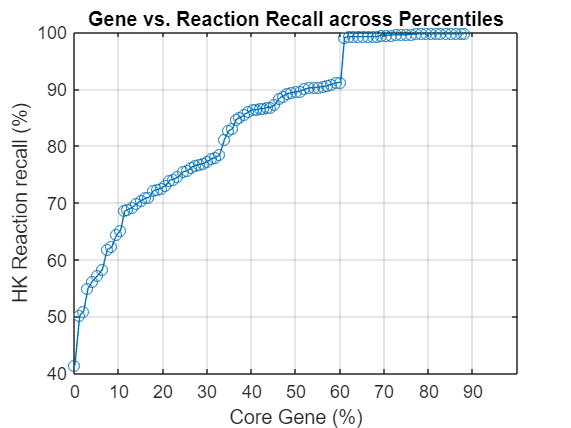


% CORE GENE INCLUSION VS HOUSEKEEPING REACTIONS RECALL
plot(HK_CG_G, HK_CR_R_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('HK Reaction recall (%)');
title('Gene vs. Reaction Recall across Percentiles');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_HKReaction_1.png');

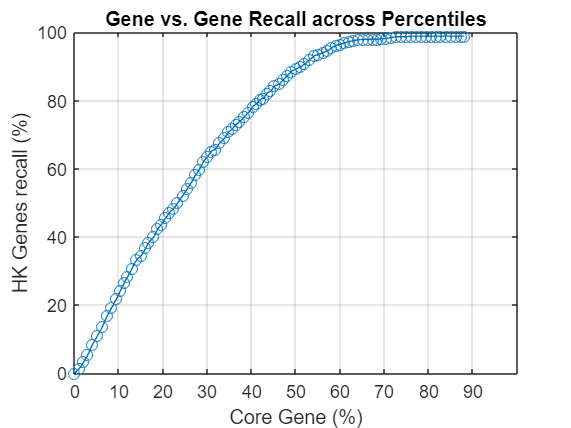


% CORE GENE INCLUSION VS HOUSEKEEPING GENES RECALL
plot(HK_CG_G, HK_CG_G_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('HK Genes recall (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_HKGene_1.png');

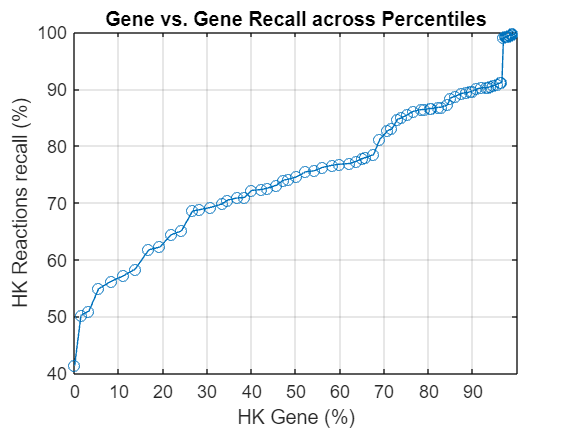


% HOUSEKEEPING GENE RECALL VS HOUSEKEEPING REACTIONS RECALL
plot(HK_CG_G_recall_values, HK_CR_R_recall_values, 'o-');
xlabel('HK Gene (%)');
ylabel('HK Reactions recall (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:max(HK_CG_G_recall_values));

% Save the plot
saveas(gcf, 'HKGene_vs_HKReactions_1.png');

# TEST WHAT MARIAN SUGGESTED ABOUT PERCENTAGE OF ORs

% Pruned and unpruned data
%IMR90_Y2 = table2array(metabolic_genes(:, 8));
IMR90_Y2 = table2array(mean(metabolic_genes(:, 8), 2))

IMR90_Y2 =     2.0923
    2.2535
    1.3807
    0.5487
    1.7719
    0.0457
    0.0734
    0.1856
    0.0866
    0.3394


%IMR90_Y2_P = table2array(metabolic_genes_P(:, 8));
IMR90_Y2_P = table2array(mean(metabolic_genes_P(:, 8), 2))

IMR90_Y2_P =     2.0923
    2.2535
    1.3807
    0.5487
    1.7719
    0.0457
    0.0734
    0.0866
    0.3394
    1.7364



% Core genes and core reactions
%IMR90_Y2_coreGenes = results_CoreGenes(8, 'CoreGeneIDs');
%test = IMR90_Y2_coreGenes{1, 1};
IMR90_Y2_length = length(IMR90_Y2_P);

% for core Reactions
%IMR90_Y2_coreReact = CoreReact_Sample(1, 8)
IMR90_Y2_RLength = length(model_p.rxns);%IMR90_Y2_coreReact{1, 1})

% Initialises vectors for storing recall values
HK_CG_G_T = zeros(1, 40);
HK_CR_R_T = zeros(1, 40);
HK_CG_G_recall_values_T = zeros(1, 40);
HK_CR_R_recall_values_T = zeros(1, 40);
HK_CG_G_T_Names = {};
HK_CR_R_T_Names = {};

% Loop to iterate over each percentile
for p = 100:-1:60
    percentile_value = prctile(IMR90_Y2, p);

    % Normalises data based on the current percentile
    IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;

    % Calculate the recall for core genes
    IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
    HK_CG_G_T_Names{p} = IMR90_Y2_CG;
    HK_CG_G_T(p) = (length(IMR90_Y2_CG)/IMR90_Y2_length)*100;
    HK_CG_G_rec_T = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
    HK_CG_G_recall_T = (length(HK_CG_G_rec_T) / length(hkg_met)) * 100;
    HK_CG_G_recall_values_T(p) = HK_CG_G_recall_T;

    % Prepare the expression data
    expressionData.gene = gene_names_P;
    expressionData.value = IMR90_Y2_norm;

    % Map gene expression to reactions
    IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false'); % Maybe here with the pruned one?
    IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);

    % Calculate the recall for core reactions
    HK_CR_R_T_Names{p} = IMR90_Y2_CR;
    HK_CR_R_T(p) = (length(IMR90_Y2_CR)/IMR90_Y2_RLength)*100;
    HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
    HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
    HK_CR_R_recall_values_T(p) = HK_CR_R_recall;
end

save('HK_CG_G_T_Names_1.mat', 'HK_CG_G_T_Names');
save('HK_CR_R_T_Names_1.mat', 'HK_CR_R_T_Names');

% load the data
HK_CG_G_T_Names = load('HK_CG_G_T_Names_1.mat');
HK_CG_G_T_Names = HK_CG_G_T_Names.HK_CG_G_T_Names;
HK_CR_R_T_Names = load('HK_CR_R_T_Names_1.mat');
HK_CR_R_T_Names = HK_CR_R_T_Names.HK_CR_R_T_Names;


## Check the or and AND rules

Go throught the 60 percentile one by one, to explore the reactions that are included, and based on that, analyze the percentage of those that are coded by 'or' rules.

%% another test 
met_ens = metabolic_genes_P.Properties.RowNames;
GPR_rules = model_p.grRules;

geneRulesCount = analyzeGPRRules(met_ens, GPR_rules);

results_test = analyzeCoreElements(IMR90_Y2, IMR90_Y2_P, met_ens, model);

% Percentages test
percentages = calculatePercentages(geneRulesCount);
disp(percentages);

    single: 12.6110
       and: 8.3010
        or: 75.5625
    and_or: 3.5256



## Print the results

% Prepare the variables to store the results
percentiles = 100:-1:60;
percentOrRules = zeros(length(percentiles), 1);
percentAndRules = zeros(length(percentiles), 1);
percentSingleRules = zeros(length(percentiles), 1);
percentCombinedRules = zeros(length(percentiles), 1);

% Obtain the data from each structure inside results_tests
for i = 1:length(percentiles)
    percentileKey = sprintf('P%d', percentiles(i));
    percentOrRules(i) = results_test.(percentileKey).percentOrRules;
    percentAndRules(i) = results_test.(percentileKey).percentAndRules;
    percentSingleRules(i) = results_test.(percentileKey).percentSingleRules;
    percentCombinedRules(i) = results_test.(percentileKey).percentCombinedRules;
end

% Create a table witht the extracted data
resultsTable = table(percentiles', percentOrRules, percentAndRules, percentSingleRules, percentCombinedRules, ...
    'VariableNames', {'Percentile', 'PercentORRules', 'PercentANDRules', 'PercentSingleRules', 'PercentCombinedRules'});

% Show the table
disp(resultsTable);

    Percentile    PercentORRules    PercentANDRules    PercentSingleRules    PercentCombinedRules
    __________    ______________    _______________    __________________    ____________________

       100                 0                  0                   0                      0       
        99            98.039                  0              1.9608                      0       
        98            96.996                  0              2.1459                0.85837       
        97            93.684                  0              5.5263                0.78947       
        96            91.827                  0              7.4519                0.72115       
        95            88.841                  0              10.515                0.64378       
        94            83.056                 

## l

clear all;
close all;
clc;

gurobi_setup;


The MATLAB interface for Gurobi 10.0.1 has been installed.

The directory
    C:\gurobi1001\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.45.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   --------------------------------------------------------

The objective is linear

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab');
changeCobraSolver('gurobi', 'all');


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
Gurobi error 10009: License expired 2024-05-14
Please consult the Gurobi Quick Start Guide for details on setting up a license.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
Gurobi error 10009: License expired 2024-05-14
Please consult the Gurobi Quick Start Guide for details on setting up a license.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 


% Load the data
metabolic_genes = load("metabolic_genes.mat");
metabolic_genes = metabolic_genes.metabolic_genes;
metabolic_genes_P = load("metabolic_genes_P.mat");
metabolic_genes_P = metabolic_genes_P.metabolic_genes_P;
gene_names_P = metabolic_genes_P.Properties.RowNames;

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
model = load('SysBio_COBRA_v1.17_consensus.mat');
model = model.myModel;
h_k_g = readtable('NM2ENSG.xlsx');
model_p = load('model.mat');
model_p = model_p.model;
cd(currentFolder)

% Housekeeping
hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));

% To reactions
results_HKReact = findRxnsFromGenes_Alicia(model_p, hkg_met);

Input: string of single gene or cell array of multiple genes



% Extract unique housekeeping reaction names
fields = fieldnames(results_HKReact);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = results_HKReact.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react_unique = unique(housekeep_react);
disp(housekeep_react_unique);

    {'MAR00001'}
    {'MAR00003'}
    {'MAR00005'}
    {'MAR00006'}
    {'MAR00010'}
    {'MAR00067'}
    {'MAR00080'}
    {'MAR00091'}
    {'MAR00113'}
    {'MAR00114'}
    {'MAR00115'}
    {'MAR00117'}
    {'MAR00118'}
    {'MAR00121'}
    {'MAR00122'}
    {'MAR00129'}
    {'MAR00133'}
    {'MAR00153'}
    {'MAR00154'}
    {'MAR00155'}
    {'MAR00158'}
    {'MAR00164'}
    {'MAR00167'}
    {'MAR00170'}
    {'MAR00173'}
    {'MAR00176'}
    {'MAR00179'}
    {'MAR00183'}
    {'MAR00187'}
    {'MAR00188'}
    {'MAR00190'}
    {'MAR00191'}
    {'MAR00192'}
    {'MAR00195'}
    {'MAR00196'}
    {'MAR00199'}
    {'MAR00200'}
    {'MAR00203'}
    {'MAR00204'}
    {'MAR00208'}
    {'MAR00209'}
    {'MAR00212'}
    {'MAR00213'}
    {'MAR00216'}
    {'MAR00217'}
    {'MAR00225'}
    {'MAR00226'}
    {'MAR00232'}
    {'MAR00233'}
    {'MAR00236'}
    {'MAR00237'}
    {'MAR00240'}
    {'MAR00241'}
    {'MAR00244'}
    {'MAR00245'}
    {'MAR00248'}
    {'MAR00249'}
    {'MAR00254'}
    {'MAR00255

HK_rxns = find_housekeeping_reactions(model_p, hkg_met, 'strict')

HK_rxns = 1×1836 cell array
    {'MAR03905'}    {'MAR03907'}    {'MAR04097'}    {'MAR04108'}    {'MAR04133'}    {'MAR04281'}    {'MAR04388'}    {'MAR08357'}    {'MAR04360'}    {'MAR04365'}    {'MAR04368'}    {'MAR04371'}    {'MAR04381'}    {'MAR04391'}    {'MAR03989'}    {'MAR08592'}    {'MAR08589'}    {'MAR03944'}    {'MAR04130'}    {'MAR04131'}    {'MAR04132'}    {'MAR04303'}    {'MAR04414'}    {'MAR08767'}    {'MAR04383'}    {'MAR04400'}    {'MAR04401'}    {'MAR04402'}    {'MAR04706'}    {'MAR08768'}    {'MAR08341'}    {'MAR08344'}    {'MAR08727'}    {'MAR08729'}    {'MAR06537'}    {'MAR03853'}    {'MAR03857'}    {'MAR04087'}    {'MAR04091'}    {'MAR08497'}    {'MAR08500'}    {'MAR08501'}    {'MAR08502'}    {'MAR08503'}    {'MAR08504'}    {'MAR08506'}    {'MAR08507'}    {'MAR08508'}    {'MAR08509'}    {'MAR08511'}    {'MAR08516'}    {'MAR00153'}    {'MAR03212'}    {'MAR03797'}    {'MAR04331'}    {'MAR04459'}    {'MAR04460'}    {'MAR09804'}    {'MAR03163'}    {'MAR04052'}    {'MAR043


% Start the plotting

% Pruned and unpruned data
IMR90_Y2 = table2array(mean(metabolic_genes(:, 8), 2));
IMR90_Y2_P = table2array(mean(metabolic_genes_P(:, 8), 2));

IMR90_Y2_length = length(IMR90_Y2_P);
IMR90_Y2_RLength = length(model_p.rxns);

HK_CG_G = zeros(1, 100);
HK_CR_R = zeros(1, 100);
HK_CG_G_recall_values = zeros(1, 100);
HK_CR_R_recall_values = zeros(1, 100);

% Vectores para almacenar la desviación estándar
HK_CG_G_std = zeros(1, 100);
HK_CR_R_std = zeros(1, 100);

% Loop to iterate over each percentile
for p = 1:100
    percentile_value = prctile(IMR90_Y2, p);

    % Normalises data based on the current percentile
    IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;

    % Calculate the recall for core genes
    IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
    HK_CG_G(p) = (length(IMR90_Y2_CG) / IMR90_Y2_length) * 100;
    HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
    HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
    HK_CG_G_recall_values(p) = HK_CG_G_recall;

    % Prepare the expression data
    expressionData.gene = gene_names_P;
    expressionData.value = IMR90_Y2_norm;

    % Map gene expression to reactions
    IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false');
    IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);

    % Calculate the recall for core reactions
    HK_CR_R(p) = (length(IMR90_Y2_CR) / IMR90_Y2_RLength) * 100;
    HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
    HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
    HK_CR_R_recall_values(p) = HK_CR_R_recall;

    % Calcular la desviación estándar
    HK_CG_G_std(p) = std(IMR90_Y2_norm);
    HK_CR_R_std(p) = std(IMR90_Y2_normCR);
end

% Save the results and load them
save('HK_CG_G_1.mat', 'HK_CG_G');
save('HK_CG_G_recall_values_1.mat', 'HK_CG_G_recall_values');
save('IMR90_Y2_norm_1.mat', 'IMR90_Y2_norm');
save('IMR90_Y2_normCR_1.mat', 'IMR90_Y2_normCR');
save('HK_CR_R_1.mat', 'HK_CR_R');
save('HK_CR_R_recall_values_1.mat', 'HK_CR_R_recall_values');
save('HK_CG_G_std_1.mat', 'HK_CG_G_std');
save('HK_CR_R_std_1.mat', 'HK_CR_R_std');

% Load the data
HK_CG_G = load('HK_CG_G_1.mat');
HK_CG_G = HK_CG_G.HK_CG_G;
HK_CG_G_recall_values = load('HK_CG_G_recall_values_1.mat');
HK_CG_G_recall_values = HK_CG_G_recall_values.HK_CG_G_recall_values;
IMR90_Y2_norm = load('IMR90_Y2_norm_1.mat');
IMR90_Y2_norm = IMR90_Y2_norm.IMR90_Y2_norm;
IMR90_Y2_normCR = load('IMR90_Y2_normCR_1.mat');
IMR90_Y2_normCR = IMR90_Y2_normCR.IMR90_Y2_normCR;
HK_CR_R = load('HK_CR_R_1.mat');
HK_CR_R = HK_CR_R.HK_CR_R;
HK_CR_R_recall_values = load('HK_CR_R_recall_values_1.mat');
HK_CR_R_recall_values = HK_CR_R_recall_values.HK_CR_R_recall_values;
HK_CG_G_std = load('HK_CG_G_std_1.mat');
HK_CG_G_std = HK_CG_G_std.HK_CG_G_std;
HK_CR_R_std = load('HK_CR_R_std_1.mat');
HK_CR_R_std = HK_CR_R_std.HK_CR_R_std;

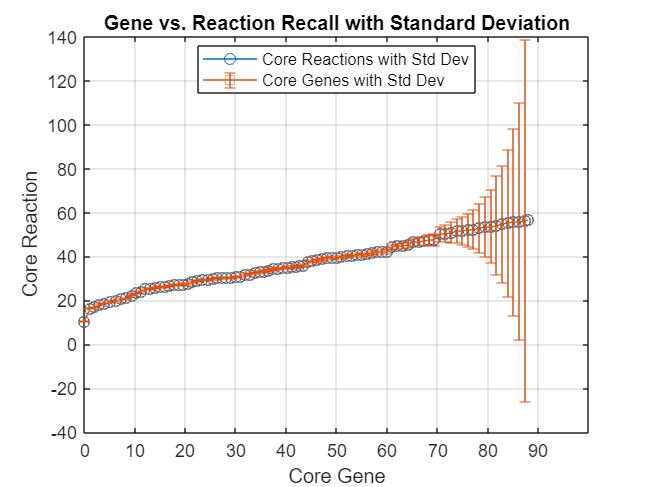

% Plot the results
figure;
errorbar(HK_CG_G, HK_CR_R, HK_CR_R_std, 'o-');
hold on;
errorbar(HK_CG_G, HK_CR_R, HK_CG_G_std, 's-');
xlabel('Core Gene');
ylabel('Core Reaction');
title('Gene vs. Reaction Recall with Standard Deviation');
legend({'Core Reactions with Std Dev', 'Core Genes with Std Dev'}, 'Location', 'best');
grid on;
xticks(0:10:90);

% Save the plot
saveas(gcf, 'Gene_vs_Reaction_Mean_with_Std.png');

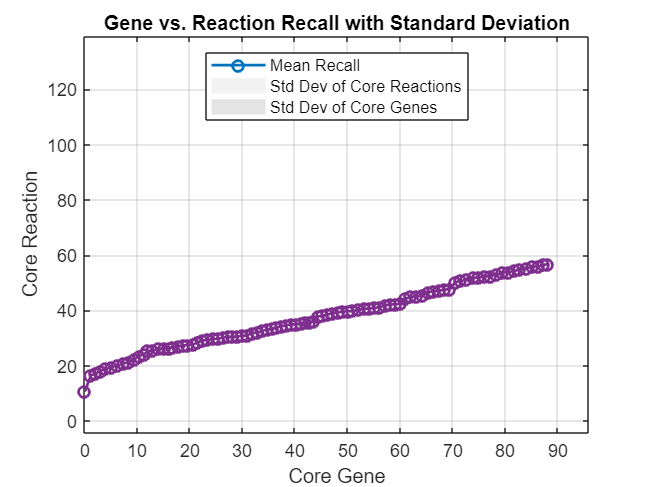

% Loop to iterate over each percentile
for p = 1:100
    percentile_value = prctile(IMR90_Y2, p);

    % Normalises data based on the current percentile
    IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;

    % Calculate the recall for core genes
    IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
    HK_CG_G(p) = (length(IMR90_Y2_CG) / IMR90_Y2_length) * 100;
    HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
    HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
    HK_CG_G_recall_values(p) = HK_CG_G_recall;

    % Prepare the expression data
    expressionData.gene = gene_names_P;
    expressionData.value = IMR90_Y2_norm;

    % Map gene expression to reactions
    IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false');
    IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);

    % Correct the calculation for core reactions at percentile 100
    % if p == 100
    %     IMR90_Y2_CR = [];
    % end

    % Calculate the recall for core reactions
    HK_CR_R(p) = (length(IMR90_Y2_CR) / IMR90_Y2_RLength) * 100;
    HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
    HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
    HK_CR_R_recall_values(p) = HK_CR_R_recall;

    % Calcular la desviación estándar
    HK_CG_G_std(p) = std(IMR90_Y2_norm);
    HK_CR_R_std(p) = std(IMR90_Y2_normCR);
end

% Plot the results with shaded areas for standard deviation
figure;
% Plot the mean values
plot(HK_CG_G, HK_CR_R, 'o-', 'LineWidth', 1.5);
hold on;

% Plot the shaded area for the standard deviation of Core Reactions
x = [HK_CG_G, fliplr(HK_CG_G)];
y = [HK_CR_R + HK_CR_R_std, fliplr(HK_CR_R - HK_CR_R_std)];
fill(x, y, [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

% Plot the shaded area for the standard deviation of Core Genes
y2 = [HK_CR_R + HK_CG_G_std, fliplr(HK_CR_R - HK_CG_G_std)];
fill(x, y2, [0.8 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

% Replot the mean values on top
plot(HK_CG_G, HK_CR_R, 'o-', 'LineWidth', 1.5);

xlabel('Core Gene');
ylabel('Core Reaction');
title('Gene vs. Reaction Recall with Standard Deviation');
legend({'Mean Recall', 'Std Dev of Core Reactions', 'Std Dev of Core Genes'}, 'Location', 'best');
grid on;
xticks(0:10:90);
ylim([0 inf]); % Ensure only the positive y-axis is shown

% Save the plot
saveas(gcf, 'Gene_vs_Reaction_Mean_with_Std_Shaded.png');